# WP2

Nota: prima di eseguire il codice assicurarsi di aver impostato come working directory di MATLAB la cartella "WP2".

## Definizione dei parametri del sistema

clear all, clc;
% x1 concentrazione del glucosio
% x2 concentrazione di insulina nei liquidi interstiziali 

p1 = 0.0151; % tasso base di rimozione del glucosio dal sangue
p2 = 0.0313; % tasso rimozione del glucosio dovuto all'insulina
p3 = 0.0097;
ge = 0.97;
ie = 0.003;
u_eq=1.003;

## Linearizzazione del sistema

Linearizziamo adesso il sistema attorno al punto di equilibrio ottenuto per l'ingresso u=1.003

% Punto di equilibrio per u=1.003
[x1_eq, x2_eq] = get_equilibrium(u_eq);
% Linearizzazione attorno al punto di equilibrio
A = [-p1-x2_eq -x1_eq; 0 -p2];
B = [0; p3];
C = [1 0];
D = [0];

x_eq = [x1_eq; x2_eq];


## Controllo della raggiungibilità

A questo punto verifichiamo al raggiungibilità del sistema linearizzato.

sys = ss(A,B,C,D);
WR = [B A*B]

WR =          0   -0.0004
    0.0097   -0.0003


rank(WR)

ans = 2

Il sistema è raggiungibile siccome il rango della matrice di raggiungibilità è pieno.

## Progettazione v1 con pole placement

La tipologia di controllore scelta è quella a retroazione di stato, essendo questa tecnica di progettazione particolarmente "potente" per il controllo di sistemi lineari. Per trovare i guadagni del controllore sono stati utilizzati diversi approcci.

Un primo tentativo di taratura è stato fatto utilizzando la tecnia del pole placement, ossia calcolando il polinomio caratteristico della matrice dinamica del sistema a ciclo chiuso e imponendo le prestazioni dinamiche desiderate tramite la scelta del tempo di assestamento $t_s \;$e del coefficiente di smorzamento $\zeta \;$. A partire dal tempo di assestamento si è utilizzata l'approssimazione $\omega_n \approx \frac{5\ldotp 8}{t_s }$ per calcolare la frequenza naturale e quindi per determinare i coefficienti desiderati per il polinomio caratteristico. 

syms zita omega_n k1 k2
K = [k1 k2];
zita=1;
ts=10;
omega_n = 5.8/ts;
charpol = charpoly(A-B*K);
desired_pol = [1, 2*zita*omega_n, omega_n^2];
sol = solve(charpol == desired_pol, [k1, k2], ReturnConditions=true);
K = [double(sol.k1) double(sol.k2)];


Si valutano ora le performance rispetto al task di regolazione con $r\left(t\right)=0\ldotp 0451\;g/l$

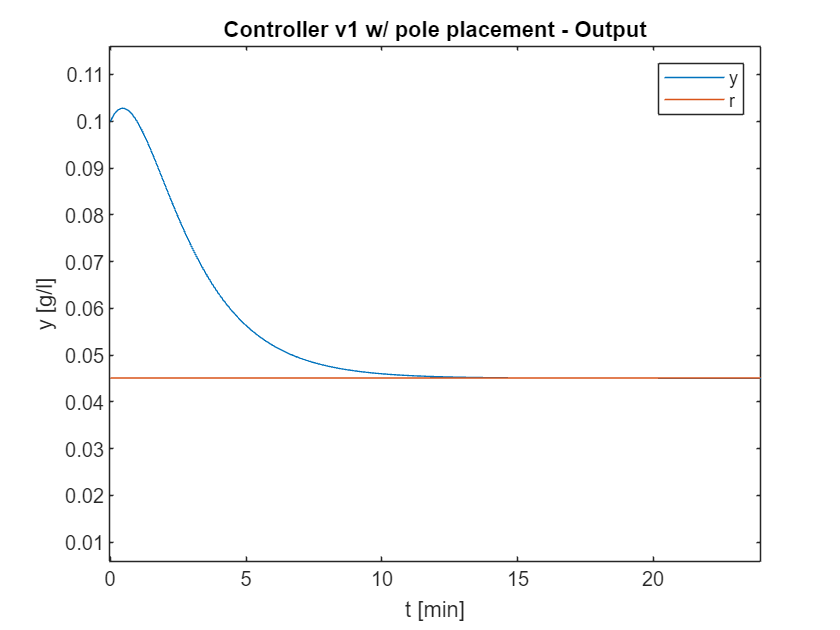

% Simulazione del sistema
simout = sim('v1_pole_placement.slx');
% Valutazione delle performance
t = simout.t.Time;
y = simout.y;
u = simout.u;
figure;
plot(t, y)
xlim([0,20])
title('Controller v1 w/ pole placement - Output')
hold on
plot(t,ones(size(t))*0.045102)
ylabel('y [g/l]')
xlabel('t [min]')

legend('y','r')

y_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 9.6092
     SettlingTime: 10.0951
      SettlingMin: 0.0451
      SettlingMax: 0.1028
        Overshoot: 128.0512
       Undershoot: 0
             Peak: 0.1028
         PeakTime: 0.4358


ylim([0 0.11])
y_stepinfo = stepinfo(y,t,x1_eq)

Relativamente alla risposta del sistema, si osservi che:

- Non sono presenti sottoelongazioni

- Il tempo di assestamento è pari a $t_{s\;} =10\;\min$

- Non ha senso valutare il tempo di salita in quanto il riferimento è al di sotto dello stato iniziale

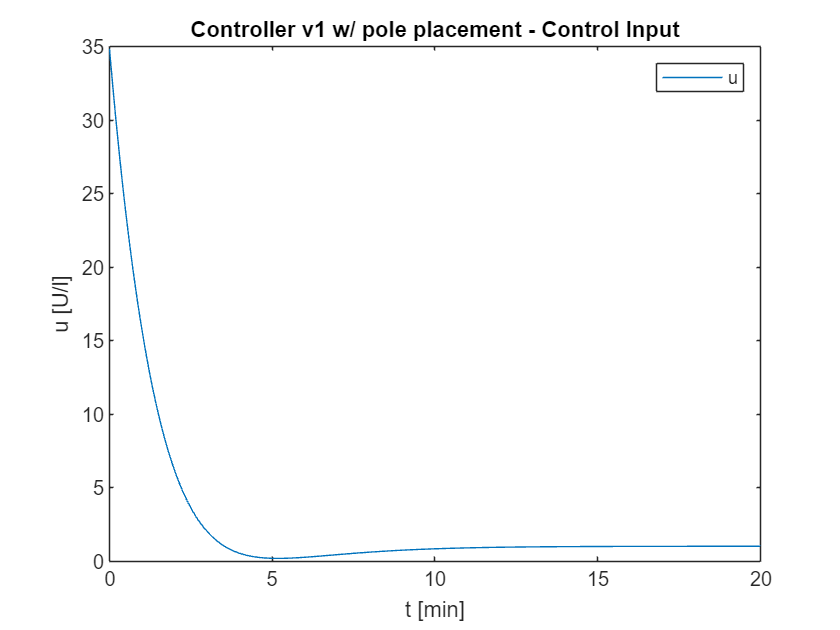

figure;
plot(t, u)
xlim([0,20])
title('Controller v1 w/ pole placement - Control Input')
ylabel('u [U/l]')
xlabel('t [min]')
legend('u')

u_stepinfo = stepinfo(u,t,u(end))

u_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 6.4228
     SettlingTime: 14.5112
      SettlingMin: 0.1772
      SettlingMax: 34.8510
        Overshoot: 3.3747e+03
       Undershoot: 0
             Peak: 34.8510
         PeakTime: 0


u_max = max(u), u_min = min(u)

u_max = 34.8510

u_min = 0.1772

Per quanto riguarda l'ingresso di controllo:

- L'ingresso ha come picco massimo 34.85 U/l, più di 2500 volte inferiore rispetto all'ingresso fornito dal controllore v0;

- L'ingresso non assume valori negativi pertanto non è affetto dai fenomeni di saturazione.

Tuttavia tale controllore non è in grado di rigettare disturbi a gradino.

## Progettazione controllore v1 con la tecnica LQR

Una seconda taratura dei guadagni è stato fatta utilizzando la tecnica LQR. Tale tecnica è stata reputata utile in quanto risulta molto più immediato ottenere un riscontro pratico dei parametri scelti per la taratura (ovvero le matrici $Q_x$ e $Q_u$) rispetto al metodo precedente. In particolare questo metodo permette di agire più direttamente sullo sforzo di controllo potendo scegliere opportunamente $Q_u$ e questo ha permesso di ottenere performance migliori. 

I pesi $Q_x$ e $Q_u$ scelti sono stati determinati a seguito di numerosi esperimenti.

Qu = 3e-6;
Qx = [10 0;0 0.1];
K = lqr(sys, Qx, Qu);
% L'LQR stabilizza il sistema linearizzato attorno a (0,0).
% La legge di controllo per il sistema originale sarà u=-K(x-x_eq)+u_eq

Si valutano ora le performance rispetto al task di regolazione con $r\left(t\right)=0\ldotp 0451\;g/l$

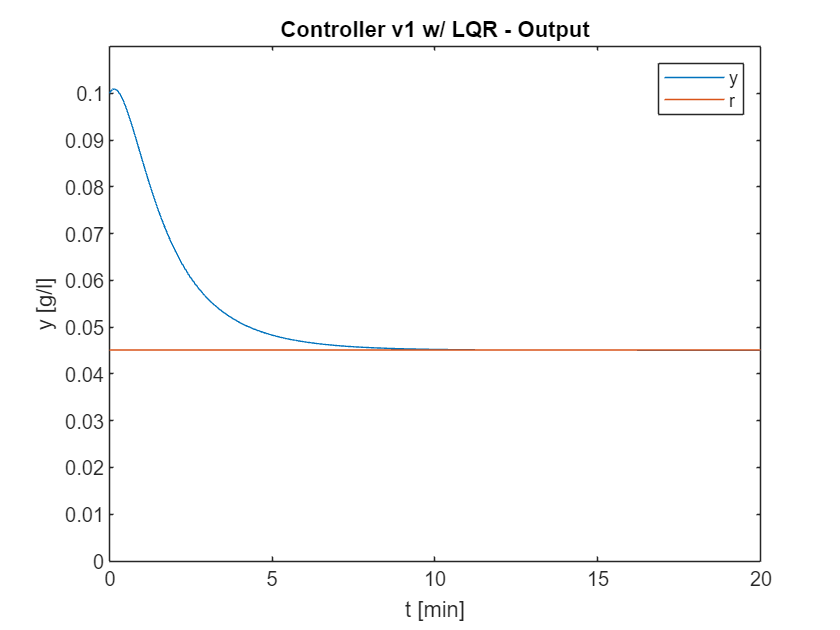

% Simulazione 
simout = sim('v1_lqr.slx');

% Valutazione delle prestazioni
t = simout.t;
t = t.Time;
y = simout.y;
u = simout.u;
figure;
plot(t, y)
xlim([0,20])
title('Controller v1 w/ LQR - Output')
hold on
plot(t,ones(size(t))*0.045102)
ylabel('y [g/l]')
xlabel('t [min]')
legend('y','r')
ylim([0 0.11])

y_stepinfo = stepinfo(y,t,x1_eq)

y_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 6.7890
     SettlingTime: 7.1555
      SettlingMin: 0.0451
      SettlingMax: 0.1009
        Overshoot: 123.8984
       Undershoot: 0
             Peak: 0.1009
         PeakTime: 0.1464


Relativamente alla risposta del sistema, si osservi che:

- Non sono presenti sottoelongazioni

- Il tempo di assestamento è pari a $t_{s\;} =7\ldotp 15\;\min$

- Non ha senso valutare il tempo di salita in quanto il riferimento è al di sotto dello stato iniziale

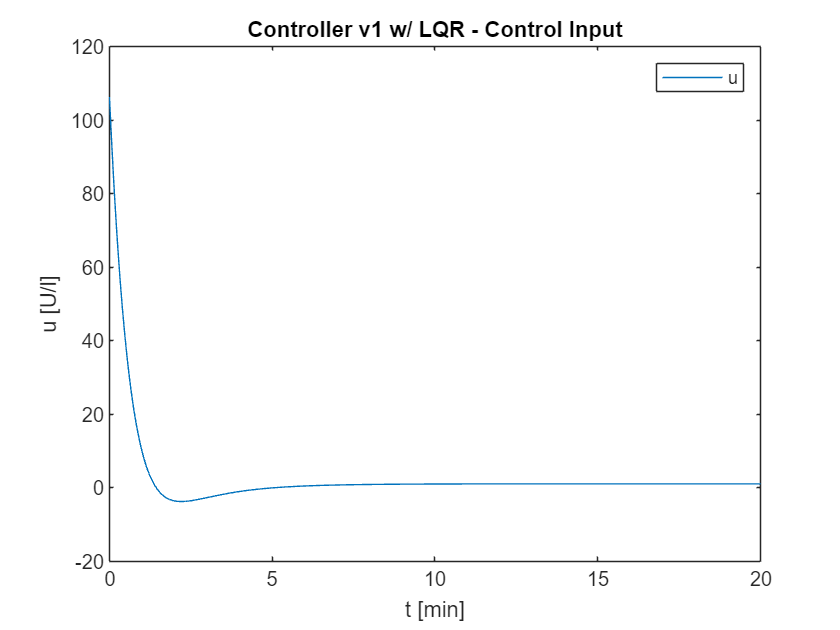

figure;
plot(t, u)
xlim([0,20])
title('Controller v1 w/ LQR - Control Input')
ylabel('u [U/l]')
xlabel('t [min]')
legend('u')

u_stepinfo = stepinfo(u,t,u(end))

u_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 3.9882
     SettlingTime: 11.7168
      SettlingMin: -3.8160
      SettlingMax: 106.2546
        Overshoot: 1.0495e+04
       Undershoot: 380.5181
             Peak: 106.2546
         PeakTime: 0


u_max = max(u), u_min = min(u)

u_max = 106.2546

u_min = -3.8160

Per quanto riguarda l'ingresso di controllo:

- L'ingresso ha come picco massimo 106.25 U/l, più di 850 volte inferiore rispetto all'ingresso fornito dal controllore v0;

- L'ingresso ha un picco minimo di -3.8 U/l pertanto non è particolarmente affetto dai fenomeni di saturazione (rispetto al controllore v0).

Tuttavia tale controllore non è in grado di rigettare disturbi a gradino.

## Progettazione con LQI

Infine, si è progettato un controllore con la tecnica di controllo l'LQI, una variante del controllo LQR. Questa tecnica introduce un'azione integrale che è in grado di compensare tutti i disturbi additivi costanti sull'ingresso di controllo. Un esempio di disturbo additivo sul nostro sistema può essere legato all'incertezza del parametro additivo $p_3 {\;i}_e$ che agisce sull'ingresso di controllo. Altri esempi di disturbi additivi possono essere legati ad attuatori difettosi oppure all'incertezza sul modello.

Controlliamo la raggiungibilità del sistema a stato esteso:

WR = [B A*B]

sys = ss(A,B,C,D);

Qu = 6e-6;

K = 1.0e+03 *

   -1.2724    0.1656    0.4082


S =    28.6720   -0.7871   -9.1758
   -0.7871    0.1024    0.2525
   -9.1758    0.2525    6.0990


e =    -0.3091
   -0.5010
   -1.1525


Qx = [10 0 0;0 0.1 0;0 0 1];
[K,S,e] = lqi(sys,Qx,Qu,0)

Si valutano ora le performance rispetto al task di regolazione con $r\left(t\right)=0\ldotp 0451\;g/l$

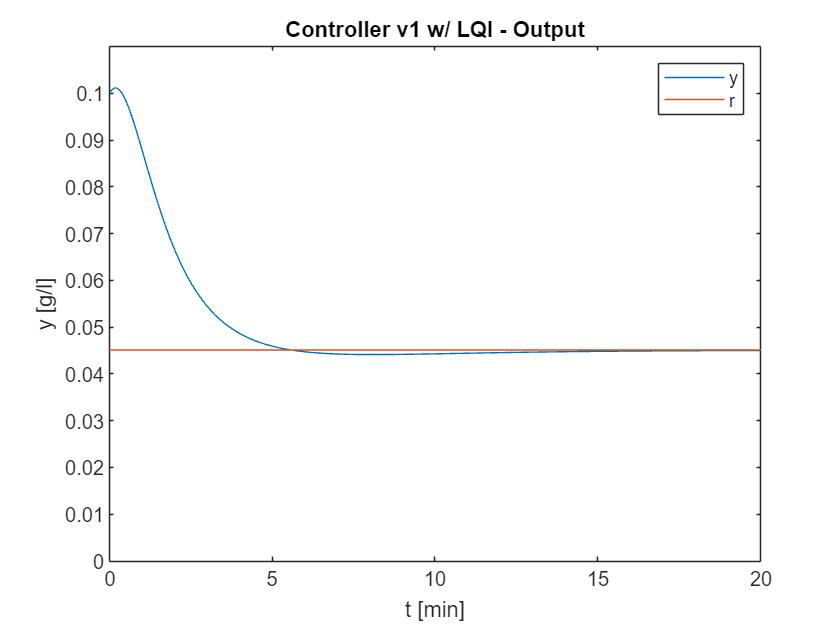

% Simulazione del sistema
enable_disturbances = 0;
simout = sim('v1_lqi.slx');
% valutazione delle performance
t = simout.t;
t = t.Time;
y = simout.y;
u = simout.u;
figure;
plot(t, y)
xlim([0,20])
title('Controller v1 w/ LQI - Output')
hold on
plot(t,ones(size(t))*0.045102)
ylabel('y [g/l]')
xlabel('t [min]')
legend('y','r')

ylim([0 0.11])

y_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 4.8652
     SettlingTime: 8.8143
      SettlingMin: 0.0441
      SettlingMax: 0.1012
        Overshoot: 124.4542
       Undershoot: 0
             Peak: 0.1012
         PeakTime: 0.1722


y_stepinfo = stepinfo(y,t,x1_eq)

ans = 0.0441

min(y)

Relativamente alla risposta del sistema, si osservi che:

- È presente una minima sottoelongazione del $2%$

- Il tempo di assestamento è pari a $t_{s\;} =7\ldotp 15\;\min$

- Non ha senso valutare il tempo di salita in quanto il riferimento è al di sotto dello stato iniziale

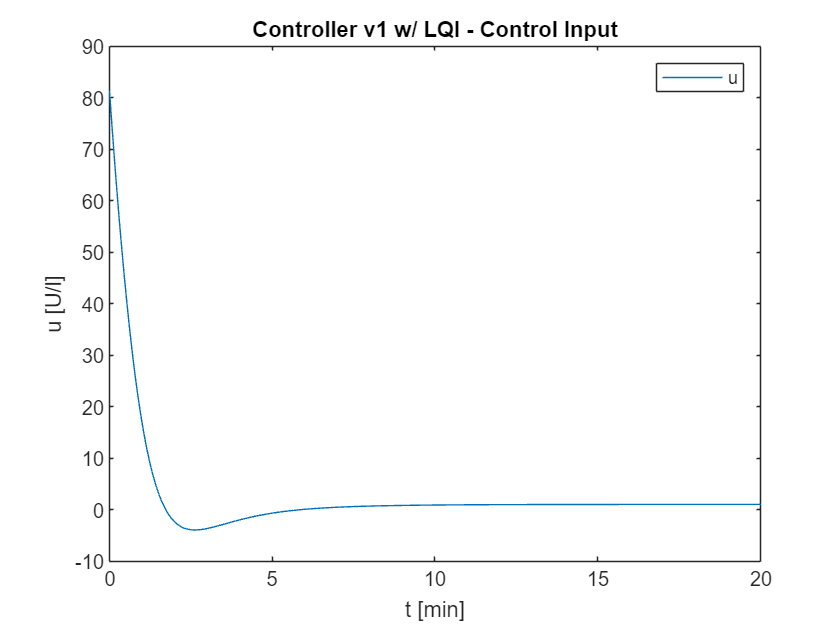

figure;
plot(t, u)
xlim([0,20])
title('Controller v1 w/ LQI - Control Input')
ylabel('u [U/l]')
xlabel('t [min]')
legend('u')

u_stepinfo = stepinfo(u,t,u(end))

u_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 5.0975
     SettlingTime: 13.9998
      SettlingMin: -3.9706
      SettlingMax: 81.3953
        Overshoot: 8.0152e+03
       Undershoot: 395.8741
             Peak: 81.3953
         PeakTime: 0


u_max = max(u), u_min = min(u)

u_max = 81.3953

u_min = -3.9706

Per quanto riguarda l'ingresso di controllo:

- L'ingresso ha come picco massimo 81.39 U/l, più di 1100 volte inferiore rispetto all'ingresso fornito dal controllore v0;

- L'ingresso ha un picco minimo di -3.97 U/l pertanto non è particolarmente affetto dai fenomeni di saturazione (rispetto al controllore v0).

Tale controllore ha una sottoelongazione leggermente peggiore rispetto a quella dei controllori precedenti. Tuttavia tutte le prestazioni sono di gran lunga migliori rispetto a quelle del controllore v0, e rispetto agli altri controllori tarati questo ha il grande vantaggio di rigettare disturbi additivi costanti sull'ingresso u. Dunque si è deciso di scegliere questo controllore tra tutti quelli proposti nel WP2. Nel seguito si mostra il comportamento del controllore in presenza di disturbi a gradino.

#### Simulazione del controllore LQI in presenza di disturbo a gradino

Il sistema è stato simulato con disturbo additivo a gradino che agisce al tempo $t=5\min$ con un ampiezza di -50U/l. Il gradino ad ampiezza negativa permette di simulare un picco glicemico nel paziente (o più in generale un'incertezza sul modello).

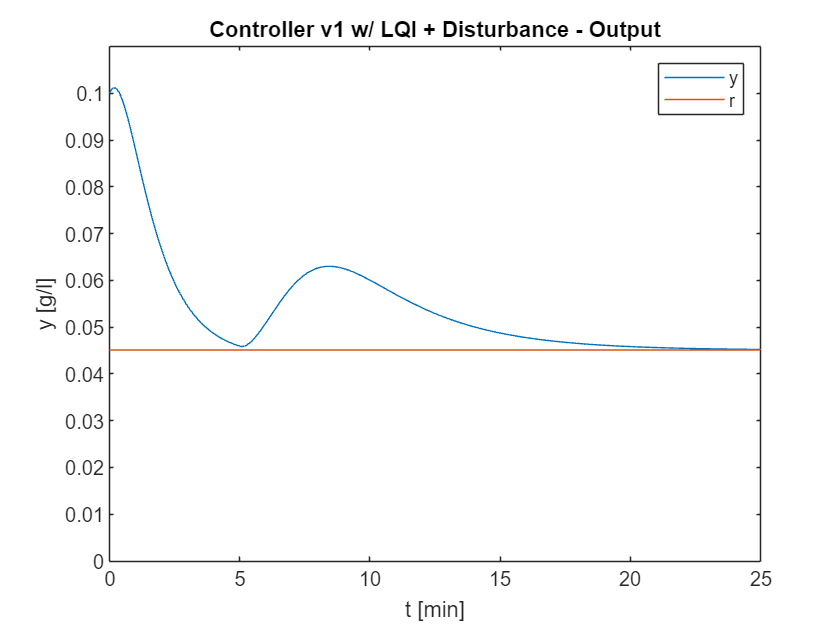

% Simulazione del sistema
enable_disturbances = 1;
simout = sim('v1_lqi.slx');
% valutazione delle performance
t = simout.t;
t = t.Time;
y = simout.y;
u = simout.u;
figure;
plot(t, y)
xlim([0,25])
title('Controller v1 w/ LQI + Disturbance - Output')
hold on
plot(t,ones(size(t))*0.045102)
ylabel('y [g/l]')
xlabel('t [min]')
legend('y','r')
ylim([0 0.11])

Osserviamo come in circa 17 min il disturbo sia assorbito completamente dal controllore.

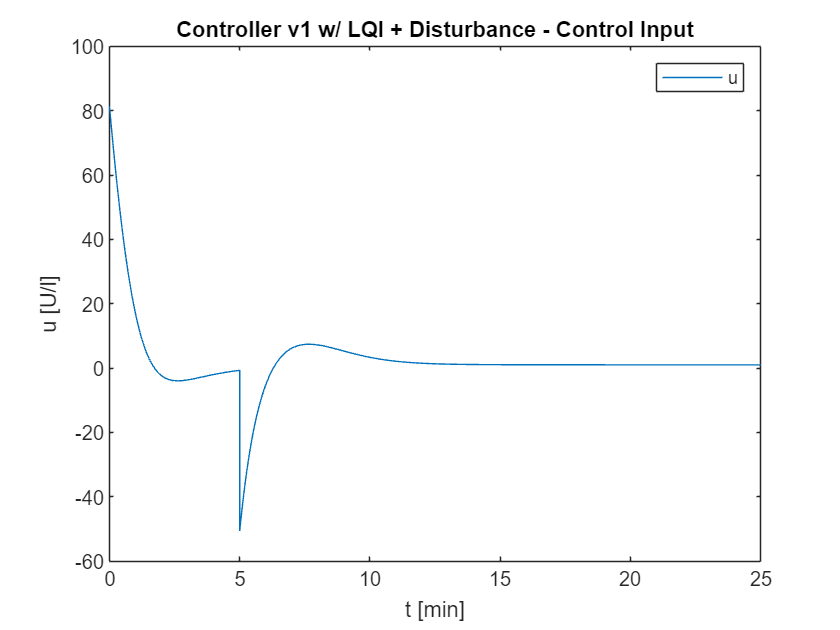

figure;
plot(t, u)
xlim([0,25])
title('Controller v1 w/ LQI + Disturbance - Control Input')
ylabel('u [U/l]')
xlabel('t [min]')
legend('u')

Il grafico dell'ingresso di controllo permette di apprezzare l'entita del disturbo. Si osservi che tale disturbo non ha significato fisico ma piuttosto modella un'incertezza sul modello o un picco glicemico nel paziente.